clc;clear all;close all;
m1=0.75;
m2=0.5;
P1=80;
P2=50;
k1=100;
k2=100;
A=[0 0 1 0;
   0 0 0 1;
   (-k1-k2)/m1 k2/m1 (-P1-P2)/m1 P2/m1;
   k2/m2  -k2/m2  P2/m2 -P2/m2];
B=[0 0; 0 0; 1/m1 0; 0 1/m2;];
C=[eye(2) zeros(2)]

C =      1     0     0     0
     0     1     0     0


D=[zeros(2)];

Q1=diag([100 100 1 1])

Q1 =    100     0     0     0
     0   100     0     0
     0     0     1     0
     0     0     0     1


Q2=diag([10000 20000 1 1])

Q2 =        10000           0           0           0
           0       20000           0           0
           0           0           1           0
           0           0           0           1


R1=diag([0.01 0.01])

R1 =     0.0100         0
         0    0.0100


R2=diag([0.01 0.01])

R2 =     0.0100         0
         0    0.0100



K1=lqr(A,B,Q1,R1)

K1 =    34.6819   17.7461    1.1418    0.9890
   29.8258   52.4280    1.4835    2.4438


K2=lqr(A,B,Q2,R2)

K2 = 1.0e+03 *

    0.8231    0.1488    0.0079    0.0058
    0.0437    1.3204    0.0086    0.0168



Kr1=inv(-(C-D*K1)*(A-B*K1)^-1*B+D)

Kr1 =   234.6819  -82.2539
  -70.1742  152.4280


Kr2=inv(-(C-D*K2)*(A-B*K2)^-1*B+D)

Kr2 = 1.0e+03 *

    1.0231    0.0488
   -0.0563    1.4204



GCL1=ss(A-B*K1,B*Kr1,C-D*K1,D*Kr1)

GCL1 =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  -312.9   109.7  -174.9   65.35
   x4   140.3  -304.9   97.03  -104.9
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3   312.9  -109.7
   x4  -140.3   304.9
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


GCL2=ss(A-B*K2,B*Kr2,C-D*K2,D*Kr2)

GCL2 =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3   -1364  -65.09  -183.9      59
   x4   112.6   -2841   82.74  -133.6
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3    1364   65.09
   x4  -112.6    2841
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


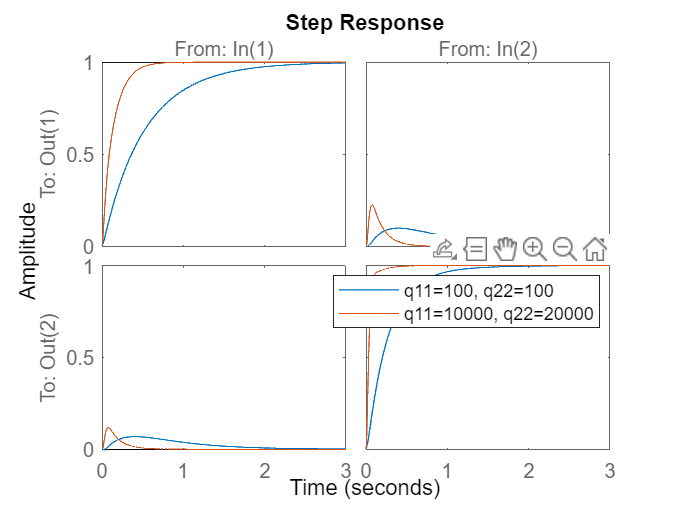


step(GCL1,3);hold on;
step(GCL2,3);
legend('q11=100, q22=100','q11=10000, q22=20000')